파라미터 설정 syms

clear;
syms l1 l2 m1 m2 th1 th2 dth1 dth2 ddth1 ddth2 I1xx I1xy I1xz I1yx I1yy I1yz I1zx I1zy I1zz...
    I2xx I2xy I2xz I2yx I2yy I2yz I2zx I2zy I2zz gy 
g = [0;gy;0];
n = 2;
assume([l1 l2 m1 m2 th1 th2 dth1 dth2 ddth1 ddth2 I1xx I1xy I1xz I1yx I1yy I1yz I1zx I1zy I1zz gy...
    I2xx I2xy I2xz I2yx I2yy I2yz I2zx I2zy I2zz],"real");
c1= cos(th1);c2 = cos(th2);c12 = cos(th1+th2);
s1= sin(th1);s2 = sin(th2);s12 = sin(th1+th2);
lc1 = l1/2;
lc2 = l2/2;

각 무게중심에서의 위치 p1, p2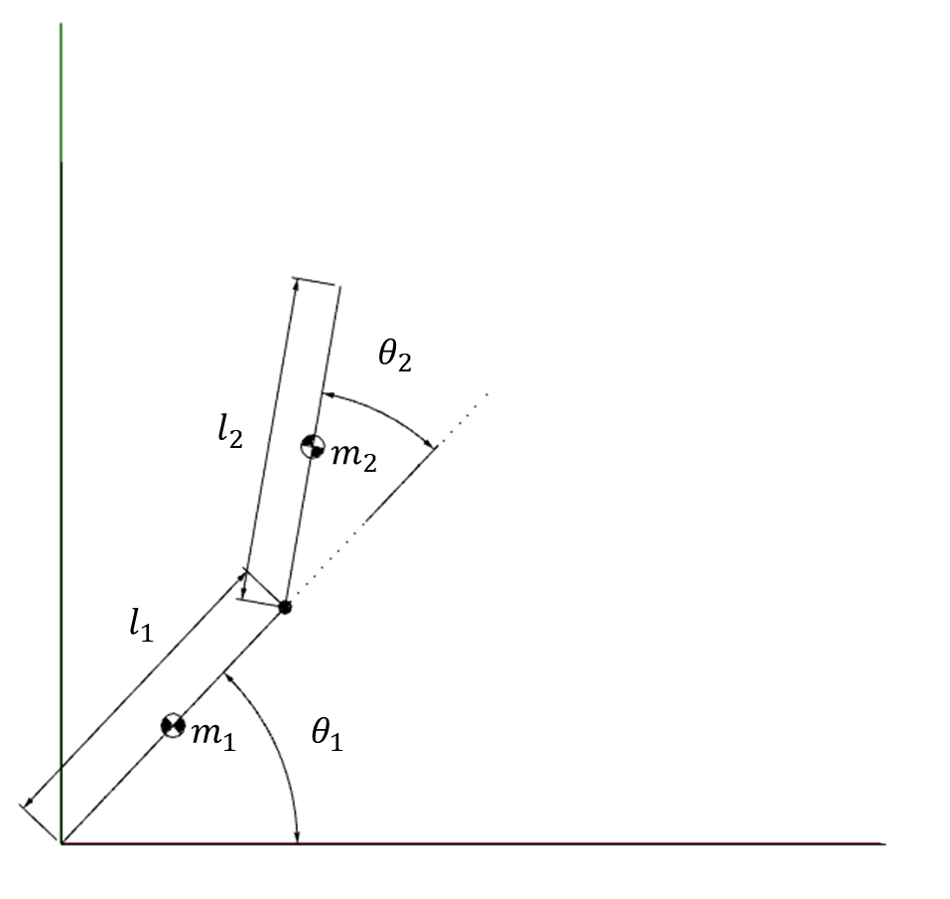


p1 = [lc1*c1;...
      lc1*s1;...
      0];
p2 = [l1*c1+lc2*c12;...
      l1*s1+lc2*s12;...
      0];
 q = [th1,th2]';

각 무게중심에서의 속도 vc1,vc2

dq = [dth1,dth2]';
ddq = [ddth1,ddth2]';
Jvc1 = [-lc1*s1 0;...
        lc1*c1 0;...
            0  0];
Jvc2 = [-l1*s1-lc2*s12,-lc2*s12;...
       l1*c1+lc2*c12, lc2*c12;...
        0 ,0];
vc1 = Jvc1*dq;
vc2 = Jvc2*dq;

Jw1 = [0,0;...
       0,0;...
       1,0];
Jw2 = [0,0;...
       0,0;...
       1,1];
w1 = Jw1*dq;
w2 = Jw2*dq;


R1 = [c1 -s1 0;...
      s1 c1 0;...
      0   0 1];
R2 = [c12 -s12 0;...
      s12 c12 0;...
      0   0 1];
I1 = [I1xx I1xy I1xz;...
      I1yx I1yy I1yz;...
      I1zx I1zy I1zz]    

$$I1 = \left(\begin{array}{ccc} \mathrm{I1xx} & \mathrm{I1xy} & \mathrm{I1xz}\\ \mathrm{I1yx} & \mathrm{I1yy} & \mathrm{I1yz}\\ \mathrm{I1zx} & \mathrm{I1zy} & \mathrm{I1zz} \end{array}\right)$$

I2 = [I2xx I2xy I2xz;...
      I2yx I2yy I2yz;...
      I2zx I2zy I2zz]  

$$I2 = \left(\begin{array}{ccc} \mathrm{I2xx} & \mathrm{I2xy} & \mathrm{I2xz}\\ \mathrm{I2yx} & \mathrm{I2yy} & \mathrm{I2yz}\\ \mathrm{I2zx} & \mathrm{I2zy} & \mathrm{I2zz} \end{array}\right)$$

Kinetic Energy 

K = 1/2*m1*vc1'*vc1+1/2*m2*vc2'*vc2+1/2*w1'*R1*I1*R1'*w1...
    +1/2*w2'*R2*I2*R2'*w2

$$K = \frac{\mathrm{I1zz}\,{{\mathrm{dth}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{dth}}_{1}\,\left(\frac{l_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\cos\left({\mathrm{th}}_{1}\right)\right)+\frac{{\mathrm{dth}}_{2}\,l_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{dth}}_{1}\,\left(\frac{l_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\sin\left({\mathrm{th}}_{1}\right)\right)+\frac{{\mathrm{dth}}_{2}\,l_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}\right)}^{2}}{2}+\mathrm{I2zz}\,\left({\mathrm{dth}}_{1}+{\mathrm{dth}}_{2}\right)\,\left(\frac{{\mathrm{dth}}_{1}}{2}+\frac{{\mathrm{dth}}_{2}}{2}\right)+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}\,{\cos\left({\mathrm{th}}_{1}\right)}^{2}}{8}+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}\,{\sin\left({\mathrm{th}}_{1}\right)}^{2}}{8}$$

Dq = m1*Jvc1'*Jvc1+Jw1'*R1*I1*R1'*Jw1+...
    m2*Jvc2'*Jvc2+Jw2'*R2*I2*R2'*Jw2;
Dq = simplify(Dq);


Potential Energy

P1 = m1*g'*p1;
P2 = m2*g'*p2;
P = P1+P2;

Lagrangian 

L = K-P

$$L = \begin{array}{l} \frac{\mathrm{I1zz}\,{{\mathrm{dth}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{dth}}_{1}\,\left(\frac{l_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\cos\left({\mathrm{th}}_{1}\right)\right)+\frac{{\mathrm{dth}}_{2}\,l_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{dth}}_{1}\,\sigma_{1}+\frac{{\mathrm{dth}}_{2}\,l_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}\right)}^{2}}{2}+\mathrm{I2zz}\,\left({\mathrm{dth}}_{1}+{\mathrm{dth}}_{2}\right)\,\left(\frac{{\mathrm{dth}}_{1}}{2}+\frac{{\mathrm{dth}}_{2}}{2}\right)-\mathrm{gy}\,m_{2}\,\sigma_{1}-\frac{\mathrm{gy}\,l_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\right)}{2}+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}\,{\cos\left({\mathrm{th}}_{1}\right)}^{2}}{8}+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}\,{\sin\left({\mathrm{th}}_{1}\right)}^{2}}{8}\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\sin\left({\mathrm{th}}_{1}\right) \end{array}$$

L = simplify(L)

$$L = \frac{\mathrm{I1zz}\,{{\mathrm{dth}}_{1}}^{2}}{2}+\frac{\mathrm{I2zz}\,{{\mathrm{dth}}_{1}}^{2}}{2}+\frac{\mathrm{I2zz}\,{{\mathrm{dth}}_{2}}^{2}}{2}+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dth}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{8}+\mathrm{I2zz}\,{\mathrm{dth}}_{1}\,{\mathrm{dth}}_{2}-\frac{\mathrm{gy}\,l_{2}\,m_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+\frac{{\mathrm{dth}}_{1}\,{\mathrm{dth}}_{2}\,{l_{2}}^{2}\,m_{2}}{4}-\frac{\mathrm{gy}\,l_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\right)}{2}-\mathrm{gy}\,l_{1}\,m_{2}\,\sin\left({\mathrm{th}}_{1}\right)+\frac{{{\mathrm{dth}}_{1}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)}{2}+\frac{{\mathrm{dth}}_{1}\,{\mathrm{dth}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)}{2}$$

L_ = 1/2*dq'*Dq*dq-P

$$L\_ = \begin{array}{l} {\mathrm{dth}}_{1}\,\left(\frac{{\mathrm{dth}}_{2}\,\sigma_{1}}{2}+\frac{{\mathrm{dth}}_{1}\,\left(\mathrm{I1zz}+\mathrm{I2zz}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{4}+l_{1}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\right)}{2}\right)+{\mathrm{dth}}_{2}\,\left(\frac{{\mathrm{dth}}_{2}\,\left(\sigma_{2}+\mathrm{I2zz}\right)}{2}+\frac{{\mathrm{dth}}_{1}\,\sigma_{1}}{2}\right)-\mathrm{gy}\,m_{2}\,\left(\frac{l_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\sin\left({\mathrm{th}}_{1}\right)\right)-\frac{\mathrm{gy}\,l_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+\frac{l_{1}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\,l_{2}}{2}+\mathrm{I2zz}\\ \sigma_{2}=\frac{m_{2}\,{l_{2}}^{2}}{4} \end{array}$$

L_ = simplify(L_)

$$L\_ = \begin{array}{l} {\mathrm{dth}}_{1}\,\left(\frac{{\mathrm{dth}}_{2}\,\sigma_{1}}{2}+\frac{{\mathrm{dth}}_{1}\,\left(\mathrm{I1zz}+\mathrm{I2zz}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{4}+l_{1}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\right)}{2}\right)+{\mathrm{dth}}_{2}\,\left(\frac{{\mathrm{dth}}_{2}\,\left(\sigma_{2}+\mathrm{I2zz}\right)}{2}+\frac{{\mathrm{dth}}_{1}\,\sigma_{1}}{2}\right)-\mathrm{gy}\,m_{2}\,\left(\frac{l_{2}\,\sin\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\sin\left({\mathrm{th}}_{1}\right)\right)-\frac{\mathrm{gy}\,l_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+\frac{l_{1}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\,l_{2}}{2}+\mathrm{I2zz}\\ \sigma_{2}=\frac{m_{2}\,{l_{2}}^{2}}{4} \end{array}$$

simplify(L_-L)

$$ans = 0$$

Christoffel symbols 

c ={}


c =

  0×0 비어 있는 cell 배열



for i =1:1:n
    for j =1:1:n
        for k = 1:1:n
            c{i,j,k} = 1/2*( diff(Dq(k,j),q(i))+ diff(Dq(k,i),q(j))-diff(Dq(i,j),q(k)))
        end
    end
end

c = 1×1 cell 배열
    {1×1 sym}


c = 1×1×2 cell 배열
c(:,:,1) = 

    {1×1 sym}


c(:,:,2) = 

    {1×1 sym}


c = 1×2×2 cell 배열
c(:,:,1) = 

    {1×1 sym}    {1×1 sym}


c(:,:,2) = 

    {1×1 sym}    {0×0 double}


c = 1×2×2 cell 배열
c(:,:,1) = 

    {1×1 sym}    {1×1 sym}


c(:,:,2) = 

    {1×1 sym}    {1×1 sym}


c = 2×2×2 cell 배열
c(:,:,1) = 

    {1×1 sym}    {1×1 sym   }
    {1×1 sym}    {0×0 double}


c(:,:,2) = 

    {1×1 sym   }    {1×1 sym   }
    {0×0 double}    {0×0 double}


c = 2×2×2 cell 배열
c(:,:,1) = 

    {1×1 sym}    {1×1 sym   }
    {1×1 sym}    {0×0 double}


c(:,:,2) = 

    {1×1 sym}    {1×1 sym   }
    {1×1 sym}    {0×0 double}


c = 2×2×2 cell 배열
c(:,:,1) = 

    {1×1 sym}    {1×1 sym}
    {1×1 sym}    {1×1 sym}


c(:,:,2) = 

    {1×1 sym}    {1×1 sym   }
    {1×1 sym}    {0×0 double}


c = 2×2×2 cell 배열
c(:,:,1) = 

    {1×1 sym}    {1×1 sym}
    {1×1 sym}    {1×1 sym}


c(:,:,2) = 

    {1×1 sym}    {1×1 sym}
    {1×1 sym}    {1×1 sym}


Centrifugal and Coriolis matrix form 

for k = 1:1:n
    for j = 1:1:n
        for i = 1:1:n
            C(k,j) = c{i,j,k}*dq(i);
        end
    end
end

Gravity Vector

g_vec={}


g_vec =

  0×0 비어 있는 cell 배열



for i =1:1:n
    g_vec{i} = diff(P,q(i))
end

g_vec = 1×1 cell 배열
    {1×1 sym}


g_vec = 1×2 cell 배열
    {1×1 sym}    {1×1 sym}


g_vec = g_vec'

g_vec = 2×1 cell 배열
    {1×1 sym}
    {1×1 sym}


Dynamic Equations

tau = Dq*ddq+C*dq+g_vec

$$tau = \begin{array}{l} \left(\begin{array}{c} -\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left({\mathrm{th}}_{2}\right)\,{{\mathrm{dth}}_{2}}^{2}}{2}-\frac{{\mathrm{dth}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left({\mathrm{th}}_{2}\right)\,{\mathrm{dth}}_{2}}{2}+{\mathrm{ddth}}_{2}\,\sigma_{1}+{\mathrm{ddth}}_{1}\,\left(\mathrm{I1zz}+\mathrm{I2zz}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{4}+l_{1}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\right)+\mathrm{gy}\,m_{2}\,\left(\frac{l_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\cos\left({\mathrm{th}}_{1}\right)\right)+\frac{\mathrm{gy}\,l_{1}\,m_{1}\,\cos\left({\mathrm{th}}_{1}\right)}{2}\\ {\mathrm{ddth}}_{2}\,\left(\sigma_{2}+\mathrm{I2zz}\right)+{\mathrm{ddth}}_{1}\,\sigma_{1}+\frac{\mathrm{gy}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+\frac{l_{1}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\,l_{2}}{2}+\mathrm{I2zz}\\ \sigma_{2}=\frac{m_{2}\,{l_{2}}^{2}}{4} \end{array}$$

simplify(tau)

$$ans = \begin{array}{l} \left(\begin{array}{c} -\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left({\mathrm{th}}_{2}\right)\,{{\mathrm{dth}}_{2}}^{2}}{2}-\frac{{\mathrm{dth}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left({\mathrm{th}}_{2}\right)\,{\mathrm{dth}}_{2}}{2}+{\mathrm{ddth}}_{2}\,\sigma_{1}+{\mathrm{ddth}}_{1}\,\left(\mathrm{I1zz}+\mathrm{I2zz}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{4}+l_{1}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\right)+\mathrm{gy}\,m_{2}\,\left(\frac{l_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2}+l_{1}\,\cos\left({\mathrm{th}}_{1}\right)\right)+\frac{\mathrm{gy}\,l_{1}\,m_{1}\,\cos\left({\mathrm{th}}_{1}\right)}{2}\\ {\mathrm{ddth}}_{2}\,\left(\sigma_{2}+\mathrm{I2zz}\right)+{\mathrm{ddth}}_{1}\,\sigma_{1}+\frac{\mathrm{gy}\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{1}+{\mathrm{th}}_{2}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+\frac{l_{1}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)\,l_{2}}{2}+\mathrm{I2zz}\\ \sigma_{2}=\frac{m_{2}\,{l_{2}}^{2}}{4} \end{array}$$